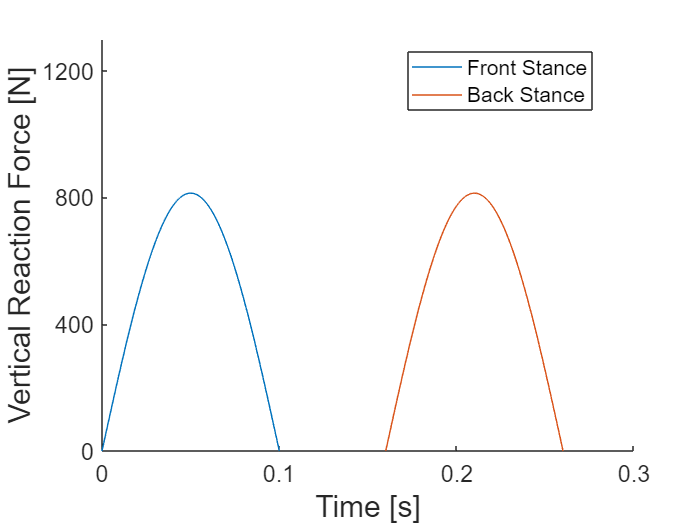

clear; close all; clc;
g = 9.81;
m = 33;             % [kg] mass of hip
I = 2.9;            % [kg m^2]
r_1 = 0.4;          % [m] thigh length
r_2 = 0.3;          % [m] shank length
body_length = 0.7;  % [m]

v = 4;

l = 0.4;                            % [m] stride length
T_swing = 0.22;                     % [s] swing time
T_stance = l/v;                     % [s] stance time
T = T_swing + T_stance;             % [s] Total gait time
T_air = (T_swing - T_stance)/2;     % [s] Time in the air

amp_y = m*g*T*pi()/(4*T_stance);
amp_x = 50;

t = 0:0.001:T_stance;
y1 = amp_y*sin((pi()/T_stance)*t);

t2 = T_stance+T_air:0.001:T-T_air;
y2 = amp_y*sin((pi()/T_stance)*(t2-(T_air+T_stance)));

x1 = -amp_x*sin((pi()/T_stance)*t);

x2 = amp_x*sin((pi()/T_stance)*(t2-(T_air+T_stance)));

figure;
hold on;
plot(t,y1);
plot(t2,y2);
set(gca,'FontSize',14)
xlabel("Time [s]","FontSize",18);
ylabel("Vertical Reaction Force [N]","FontSize",18);
set(gca,'XTick',0:0.1:0.3)
set(gca,'YTick',0:400:1200)
legend(["Front Stance","Back Stance"],"Location","Best");
axis([0 0.3 0 1300]);
hold off;

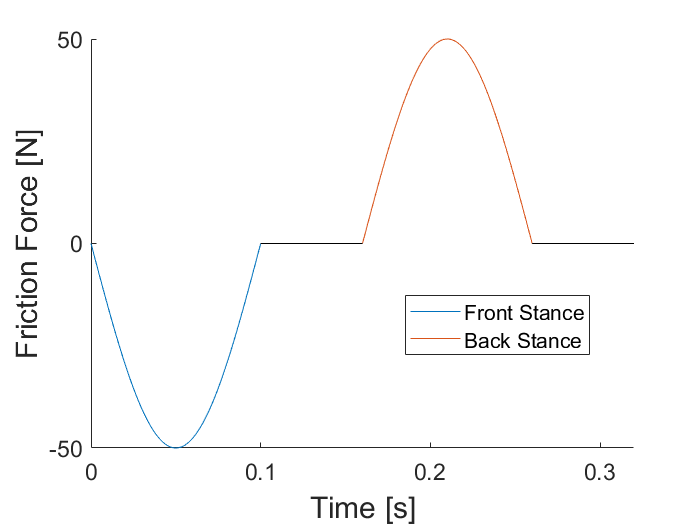


figure;
hold on;
plot(t,x1);
plot(t2,x2);
plot([T_stance,T_stance+T_air], [0, 0],'k');
plot([2*T_stance+T_air,T], [0, 0],'k');
set(gca,'FontSize',14)
xlabel("Time [s]","FontSize",18);
ylabel("Friction Force [N]","FontSize",18);
set(gca,'XTick',0:0.1:0.3)
legend(["Front Stance","Back Stance"],"Location","Best");
hold off;